% Pedro Teixeira <pedro.teix@ua.pt>
% 84715
% February 10, 2012

% Exercise 2
% p bit error rate
% 

% Let it be:
%   E : Select right answer     
%   NE: Select wrong answer

%   K : Student knows answer
%   NK: Student does not know answer

% 2a
% p(0) = (n 0) * p^0 * (1-p)^n-0
n = 100 * 8;
p = 10^-2;
i = 0;
res = (nchoosek(n, i) * p^i * (1-p)^(n-i)) * 100

res = 0.0322

% 2b
% p(1) = (n 1) * p^1 * (1-p)^n-1
n = 1000 * 8;
p = 10^-3;
i = 1;
res = (nchoosek(n, i) * p^i * (1-p)^(n-i)) * 100

res = 0.2676

% 2c
% p(>=1) = 1- p(0)
n = 200 * 8;
p = 10^-4;
i = 0;
res = (1 - (nchoosek(n, i) * p^i * (1-p)^(n-i))) * 100

res = 14.7863

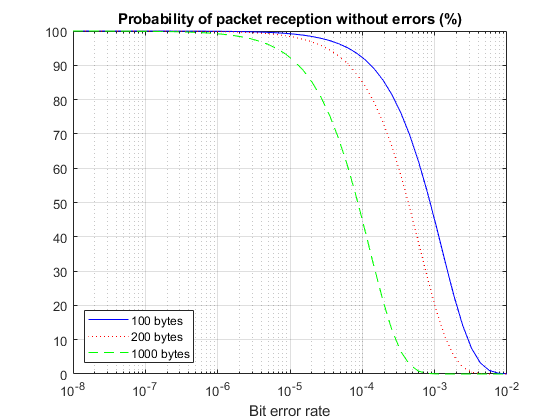

% 2d
% PAY ATTENTION TO THIS EXERCISE
% P(E) = P(E|K) * P(K) + P(E|NK) * P(NK)
p = logspace(-8, -2);
i = 0 ;  % no errors
n = 100 * 8;
f_100 = (nchoosek(n, i) .* p.^i .* (1-p).^(n-i));

n = 200 * 8;
f_200 = (nchoosek(n, i) .* p.^i .* (1-p).^(n-i));
n = 1000 * 8;
f_1000 = (nchoosek(n, i) .* p.^i .* (1-p).^(n-i));
figure(1)
semilogx(p, f_100 * 100, 'b-', p, f_200 * 100, 'r:', p, f_1000 * 100, 'g--')
title("Probability of packet reception without errors (%)")
xlabel("Bit error rate")
ylabel("")
legend('100 bytes', '200 bytes', '1000 bytes', 'location', 'SouthWest')
%axis([0 100 0 100])
grid on

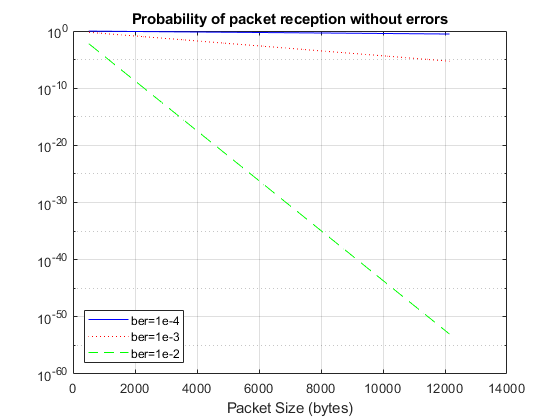

% 2e
% P(E) = P(E|K) * P(K) + P(E|NK) * P(NK)
n = linspace(64*8, 1518*8);
i = 0;   % no errors

p = 10^-4;
f_100 = 1 * p^i * (1-p).^(n-i);

p = 10^-3;
f_200 = 1 * p^i * (1-p).^(n-i);

p = 10^-2;
f_1000 = 1 * p^i * (1-p).^(n-i);

figure(2)
semilogy(n, f_100, 'b-', n, f_200, 'r:', n, f_1000, 'g--')
title("Probability of packet reception without errors")
xlabel("Packet Size (bytes)")
ylabel("")
legend('ber=1e-4', 'ber=1e-3', 'ber=1e-2', 'location', 'SouthWest')
%axis([0 100 0 100])
grid on